clc;
clear all;

% Thresholds
min_stroke_age = 0;
min_test_age = 0;
min_test_interval = 0.5;

% Get VIPS dataset
project_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction';
beh_csv = readtable(fullfile(project_dir, 'behavior', 'vips_combined_31226.csv'), 'Format', 'auto');
inc_ind = find(all([beh_csv.stroke_age >= min_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval, ...
    beh_csv.has_lesion==1],2));    
beh_csv = beh_csv(inc_ind,:);

% Plot behavior
sm = summary(categorical(beh_csv.contra_motor));
lang = summary(categorical(beh_csv.worst_lang));

bar([sm.Counts, lang.Counts]', 'stacked');
set(gca, 'XtickLabel', {'SM', 'Lang'});
box off;
ylabel('Number of Patients');
l = legend({'0-None', '0.5-Mild', '1-Moderate', '2-Severe'}); l.IconColumnWidth = 5

l =   Legend (0-None, 0.5-Mild, 1-Moderate, 2-Severe) with properties:

         String: {'0-None'  '0.5-Mild'  '1-Moderate'  '2-Severe'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7465 0.7242 0.1402 0.1706]
          Units: 'normalized'

  Show all properties


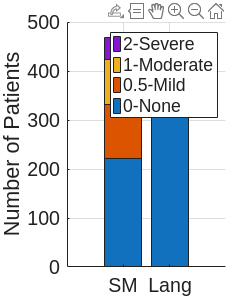

grid on; set(gcf, 'position', [0, 0, 250, 300]); set(gca, 'FontSize', 15); title('');

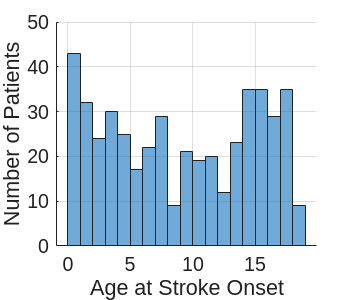

clf;
histogram(beh_csv.stroke_age, 'binWidth', 1);
ylabel('Number of Patients');
xlabel('Age at Stroke Onset');
box off;
grid on; set(gcf, 'position', [0, 0, 350, 300]); set(gca, 'FontSize', 15); title('');

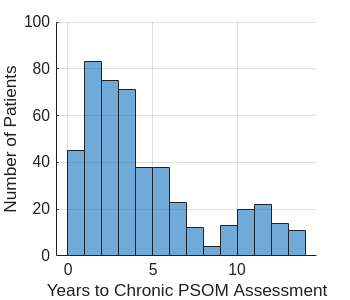

clf;
histogram(beh_csv.yrs2test, 'binWidth', 1);
ylabel('Number of Patients');
xlabel('Years to Chronic PSOM Assessment');
box off;
grid on; set(gcf, 'position', [0, 0, 350, 300]); set(gca, 'FontSize', 12); title('');